% Define the deceptive groups for blocks 3 & 4 and blocks 6 & 7
deceptiveInBlocks34 = [1, 2, 3, 7, 21, 22, 23, 24, 27, 29];
deceptiveInBlocks67 = setdiff(1:29, deceptiveInBlocks34);
deceptiveInBlocks67(deceptiveInBlocks67 == 3) = [];  % Exclude subject number 3


% Folder selection and file loading
dataFolder = uigetdir('', 'Select the folder containing all subject files');
if dataFolder == 0
    error('No folder selected. Exiting script.');
end
fileList = dir(fullfile(dataFolder, '*.mat'));

% Initialize results structure
allResults = repmat(struct(), length(fileList), 1);

% Function to calculate SCL
function SCL = calculateSCL(EDA)
    SCL = mean(EDA);
end

% Function to calculate SCR
function SCR = calculateSCR(EDA)
    [peaks, ~] = findpeaks(EDA, 'MinPeakProminence', 0.01, 'MinPeakDistance', 50);
    SCR = length(peaks);
end

% Function to calculate HRV
function HRV = calculateHRV(ECG)
    [qrs_peaks, ~] = findpeaks(ECG, 'MinPeakHeight', max(ECG)*0.5, 'MinPeakDistance', 50);
    RR_intervals = diff(qrs_peaks);
    HRV = std(RR_intervals);
end

for i = 1:length(fileList)
    fileName = fullfile(dataFolder, fileList(i).name);
    subjectNum = str2double(regexp(fileName, '\d+', 'match', 'once')); % Extract subject number from file name
    
    % Check if the file corresponds to a subject
    if ~isempty(subjectNum) && (ismember(subjectNum, deceptiveInBlocks34) || ismember(subjectNum, deceptiveInBlocks67))
        data = load(fileName);

        % Check if 'bp_data' structure exists and process
        if isfield(data, 'bp_data')
            bp_data = data.bp_data;
            
            % Validate and extract EDA and ECG data
            labels = cellstr(bp_data.labels);
            EDA_index = find(contains(lower(labels), 'eda'));
            ECG_index = find(contains(lower(labels), 'ecg'));

            if isempty(EDA_index) || isempty(ECG_index)
                disp(['EDA or ECG labels not found in file: ', fileList(i).name]);
                continue;
            end

            % Extract data for blocks 3/4 or 6/7 based on group
            blockStarts = bp_data.BLOCK_START;
            if ismember(subjectNum, deceptiveInBlocks34)
                blocksOfInterest = [3, 4];
            else
                blocksOfInterest = [6, 7];
            end

            for block = blocksOfInterest
                if block < length(blockStarts)
                    startIdx = round(blockStarts(block));
                    endIdx = round(blockStarts(block + 1)) - 1;
                else
                    startIdx = round(blockStarts(block));
                    endIdx = size(bp_data.data, 1); % Assuming last block runs till the end of data
                end

                EDA_block = bp_data.data(startIdx:endIdx, EDA_index);
                ECG_block = bp_data.data(startIdx:endIdx, ECG_index);

                % Calculate physiological parameters for each block
                allResults(i).(strcat('SCL_Block', num2str(block))) = calculateSCL(EDA_block);
                allResults(i).(strcat('SCR_Block', num2str(block))) = calculateSCR(EDA_block);
                allResults(i).(strcat('HRV_Block', num2str(block))) = calculateHRV(ECG_block);
            end
        else
            disp(['bp_data structure missing in file: ', fileList(i).name]);
        end
    else
        disp(['File ', fileList(i).name, ' does not correspond to a valid subject or is not labeled properly.']);
    end
end

disp(allResults);

  28x1 struct array with fields:

    SCL_Block3
    SCR_Block3
    HRV_Block3
    SCL_Block4
    SCR_Block4
    HRV_Block4
    SCL_Block6
    SCR_Block6
    HRV_Block6
    SCL_Block7
    SCR_Block7
    HRV_Block7



% Assuming allResults is already filled from the script above
numSubjects = length(fileList);
sclData34 = zeros(numSubjects, 2); % SCL data for blocks 3 and 4
scrData34 = zeros(numSubjects, 2); % SCR data for blocks 3 and 4
hrvData34 = zeros(numSubjects, 2); % HRV data for blocks 3 and 4
sclData67 = zeros(numSubjects, 2); % SCL data for blocks 6 and 7
scrData67 = zeros(numSubjects, 2); % SCR data for blocks 6 and 7
hrvData67 = zeros(numSubjects, 2); % HRV data for blocks 6 and 7

% Prepare the data matrices based on deception in blocks 3 & 4 and blocks 6 & 7
sclData34 = []; scrData34 = []; hrvData34 = [];
sclData67 = []; scrData67 = []; hrvData67 = [];

% Loop through all subjects and allocate data to the correct group
for i = 1:numSubjects
    subjectNum = str2double(regexp(fileList(i).name, '\d+', 'match', 'once'));

    if ismember(subjectNum, deceptiveInBlocks34)
        sclData34 = [sclData34; allResults(i).SCL_Block3, allResults(i).SCL_Block4];
        scrData34 = [scrData34; allResults(i).SCR_Block3, allResults(i).SCR_Block4];
        hrvData34 = [hrvData34; allResults(i).HRV_Block3, allResults(i).HRV_Block4];
    elseif ismember(subjectNum, deceptiveInBlocks67)
        sclData67 = [sclData67; allResults(i).SCL_Block6, allResults(i).SCL_Block7];
        scrData67 = [scrData67; allResults(i).SCR_Block6, allResults(i).SCR_Block7];
        hrvData67 = [hrvData67; allResults(i).HRV_Block6, allResults(i).HRV_Block7];
    end
end


% Define groups for ANOVA - just two blocks for simplicity here
groups = {'Block3', 'Block4'};

% Perform ANOVA for subjects deceptive in blocks 3 and 4
[p_scl_34, tbl_scl_34, stats_scl_34] = anova1(sclData34, groups, 'off');
[p_scr_34, tbl_scr_34, stats_scr_34] = anova1(scrData34, groups, 'off');
[p_hrv_34, tbl_hrv_34, stats_hrv_34] = anova1(hrvData34, groups, 'off');

% Perform ANOVA for subjects deceptive in blocks 6 and 7
[p_scl_67, tbl_scl_67, stats_scl_67] = anova1(sclData67, groups, 'off');
[p_scr_67, tbl_scr_67, stats_scr_67] = anova1(scrData67, groups, 'off');
[p_hrv_67, tbl_hrv_67, stats_hrv_67] = anova1(hrvData67, groups, 'off');

% Display ANOVA results
fprintf('ANOVA results for SCL (Blocks 3 & 4): p = %.4f\n', p_scl_34);

ANOVA results for SCL (Blocks 3 & 4): p = 0.8994


fprintf('ANOVA results for SCR (Blocks 3 & 4): p = %.4f\n', p_scr_34);

ANOVA results for SCR (Blocks 3 & 4): p = 0.3274


fprintf('ANOVA results for HRV (Blocks 3 & 4): p = %.4f\n', p_hrv_34);

ANOVA results for HRV (Blocks 3 & 4): p = 0.9541



fprintf('ANOVA results for SCL (Blocks 6 & 7): p = %.4f\n', p_scl_67);

ANOVA results for SCL (Blocks 6 & 7): p = 0.9298


fprintf('ANOVA results for SCR (Blocks 6 & 7): p = %.4f\n', p_scr_67);

ANOVA results for SCR (Blocks 6 & 7): p = 0.0011


fprintf('ANOVA results for HRV (Blocks 6 & 7): p = %.4f\n', p_hrv_67);

ANOVA results for HRV (Blocks 6 & 7): p = 0.1115


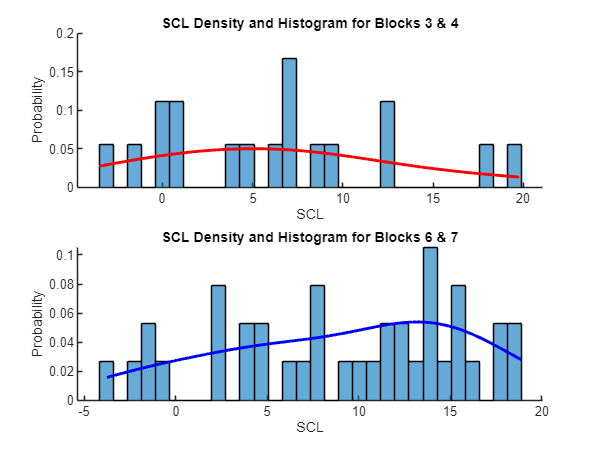

% Set number of bins for histograms
numBins = 30;

% Create figure for SCL histograms and density plots
figure;
subplot(2,1,1);
hold on;
histSCL34 = histogram(sclData34, numBins, 'Normalization', 'probability');
densitySCL34 = fitdist(sclData34(:), 'Kernel');
x_values34 = linspace(min(sclData34(:)), max(sclData34(:)), 100);
y_values34 = pdf(densitySCL34, x_values34);
plot(x_values34, y_values34, 'r-', 'LineWidth', 2);
title('SCL Density and Histogram for Blocks 3 & 4');
xlabel('SCL');
ylabel('Probability');
hold off;

subplot(2,1,2);
hold on;
histSCL67 = histogram(sclData67, numBins, 'Normalization', 'probability');
densitySCL67 = fitdist(sclData67(:), 'Kernel');
x_values67 = linspace(min(sclData67(:)), max(sclData67(:)), 100);
y_values67 = pdf(densitySCL67, x_values67);
plot(x_values67, y_values67, 'b-', 'LineWidth', 2);
title('SCL Density and Histogram for Blocks 6 & 7');
xlabel('SCL');
ylabel('Probability');
hold off;

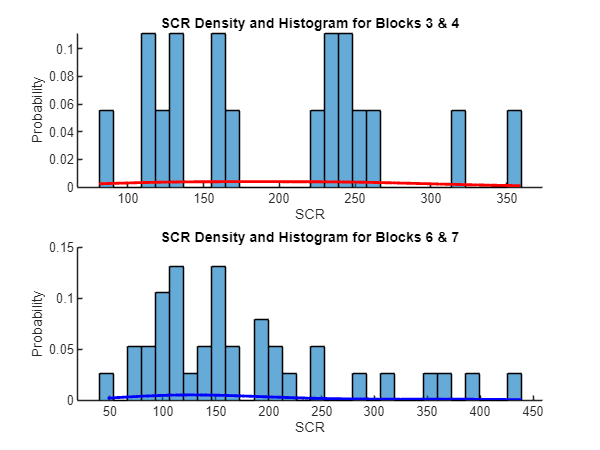


% Create figure for SCR histograms and density plots
figure;
subplot(2,1,1);
hold on;
histSCR34 = histogram(scrData34, numBins, 'Normalization', 'probability');
densitySCR34 = fitdist(scrData34(:), 'Kernel');
x_values34 = linspace(min(scrData34(:)), max(scrData34(:)), 100);
y_values34 = pdf(densitySCR34, x_values34);
plot(x_values34, y_values34, 'r-', 'LineWidth', 2);
title('SCR Density and Histogram for Blocks 3 & 4');
xlabel('SCR');
ylabel('Probability');
hold off;

subplot(2,1,2);
hold on;
histSCR67 = histogram(scrData67, numBins, 'Normalization', 'probability');
densitySCR67 = fitdist(scrData67(:), 'Kernel');
x_values67 = linspace(min(scrData67(:)), max(scrData67(:)), 100);
y_values67 = pdf(densitySCR67, x_values67);
plot(x_values67, y_values67, 'b-', 'LineWidth', 2);
title('SCR Density and Histogram for Blocks 6 & 7');
xlabel('SCR');
ylabel('Probability');
hold off;

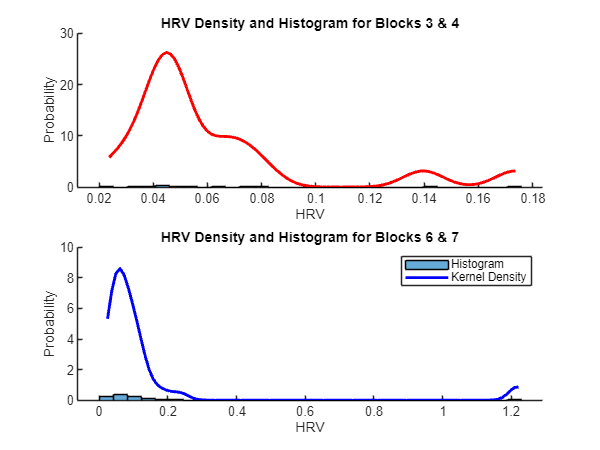


% Create figure for HRV histograms and density plots
figure;
subplot(2,1,1);
hold on;
histHRV34 = histogram(hrvData34, numBins, 'Normalization', 'probability');
densityHRV34 = fitdist(hrvData34(:), 'Kernel');
x_values34 = linspace(min(hrvData34(:)), max(hrvData34(:)), 100);
y_values34 = pdf(densityHRV34, x_values34);
plot(x_values34, y_values34, 'r-', 'LineWidth', 2);
title('HRV Density and Histogram for Blocks 3 & 4');
xlabel('HRV');
ylabel('Probability');
hold off;

subplot(2,1,2);
hold on;
histHRV67 = histogram(hrvData67, numBins, 'Normalization', 'probability');
densityHRV67 = fitdist(hrvData67(:), 'Kernel');
x_values67 = linspace(min(hrvData67(:)), max(hrvData67(:)), 100);
y_values67 = pdf(densityHRV67, x_values67);
plot(x_values67, y_values67, 'b-', 'LineWidth', 2);
title('HRV Density and Histogram for Blocks 6 & 7');
xlabel('HRV');
ylabel('Probability');
hold off;

% Add legends and make the plots prettier if needed
legend('Histogram', 'Kernel Density');